x =      1     1     0     0     1     0     1     0


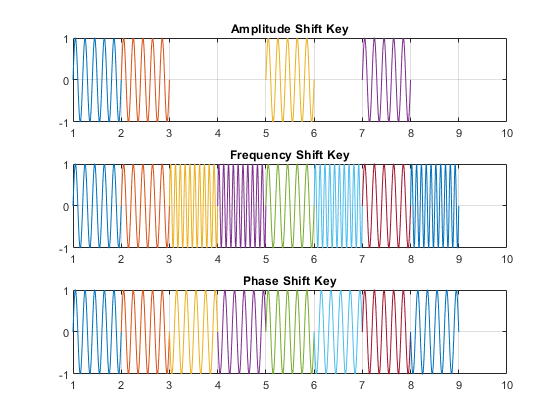

close all;
clc;
f=5;
f2=10;
x=[1 1 0 0 1 0 1 0] % input signal ;
nx=size(x,2);
i=1;
while i<nx+1
 t = i:0.001:i+1;
 if x(i)==1
 ask=sin(2*pi*f*t);
 fsk=sin(2*pi*f*t);
 psk=sin(2*pi*f*t);
 else
 ask=0;
 fsk=sin(2*pi*f2*t);
 psk=sin(2*pi*f*t+pi);
 end
 subplot(3,1,1);
 plot(t,ask);
 hold on;
 grid on;
 axis([1 10 -1 1]);
title('Amplitude Shift Key')
 subplot(3,1,2);
 plot(t,fsk);
 hold on;
 grid on;
 axis([1 10 -1 1]);
title('Frequency Shift Key')
 subplot(3,1,3);
 plot(t,psk);
 hold on;
 grid on;
 axis([1 10 -1 1]);
title('Phase Shift Key')
 i=i+1;
end